# Trabajo 1 Robótica Móvil

Autores: Sacha Varela, Geronimo Gonzalez Marino

% Limpio el espacio de trabajo
clear all, close all, clc

IMPORTANTE: Setear path de la libreria RTB en el top de la lista (puede haber errores con la interpretacion de los angulos)

## Ejercicio 1

Para el sistema de coordenadas canónico de un robot móvil (x: hacia adelante, y: hacia la izquierda, z: hacia arriba) dibujar y resolver matemáticamente el sistema de coordenadas resultante luego de aplicar las rotaciones dadas. 

% Definición de rotaciones elementales

Ry = SO3.Ry(pi/2);     % rotación 90° en Y
Rx = SO3.Rx(-pi/2);    % rotación -90° en X
Rz = SO3.Rz(pi);       % rotación 180° en Z

% Composiciones
so0 = SO3;             % Sistema original
so1 = Ry;               % solo Ry
so2 = Rx * Ry;          % Rx después de Ry
so3 = Rz * Rx * Ry;     % Rz después de Rx después de Ry

% Mostrar matrices
disp("SO1 = Ry"); disp(so1.R)

SO1 = Ry
     0     0     1
     0     1     0
    -1     0     0



disp("SO2 = Rx*Ry"); disp(so2.R)

SO2 = Rx*Ry
     0     0     1
    -1     0     0
     0    -1     0



disp("SO3 = Rz*Rx*Ry"); disp(so3.R)

SO3 = Rz*Rx*Ry
     0     0    -1
     1     0     0
     0    -1     0




% Dibujo los marcos de referencia 
figure(1); 

subplot(2,2,1); 
so0.plot(); 
title("Sistema original"); 
view(35,35); 

subplot(2,2,2); 
so1.plot(); 
title("Ry(90°) ="); 
view(35,35); 

subplot(2,2,3); 
so2.plot(); 
title("SO2 = Rx(-90°) * Ry(90°)");
view(35,35); 

subplot(2,2,4); 
so3.plot(); 
title("SO3 = Rz(180°) * Rx(-90°) * Ry(90°)"); 
view(35,35);

## Ejercicio 2

Dada los siguientes ángulos de Euler (α = 4π/7 , β = π/2 , γ = − π/3 ), con órden xyz (primero rotación en X, luego en Y y finalmente en Z) utilizando Rotación Intrínseca. Se pide: 

a) Calcular la matríz de Rotación resultante R = Rx(α)Ry(β)Rz(γ). 

b) Utilizando la matríz de rotación calculada R, extraer matemáticamente los Ángulos de Euler. Explicar.

syms alpha beta gamma   % Definir variables simbólicas

% Matrices de rotación simbólicas
Rx = [1 0 0;
      0 cos(alpha) -sin(alpha);
      0 sin(alpha) cos(alpha)];

Ry = [cos(beta) 0 sin(beta);
      0 1 0;
      -sin(beta) 0 cos(beta)];

Rz = [cos(gamma) -sin(gamma) 0;
      sin(gamma) cos(gamma) 0;
      0 0 1];

% Rotación compuesta simbólica
disp('Matriz de rotación con los angulos simbolicos');

Matriz de rotación con los angulos simbolicos


R = Rx*Ry*Rz

$$R = \left(\begin{array}{ccc} \cos\left(\beta \right)\,\cos\left(\gamma \right) & -\cos\left(\beta \right)\,\sin\left(\gamma \right) & \sin\left(\beta \right)\\ \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & -\cos\left(\beta \right)\,\sin\left(\alpha \right)\\ \sin\left(\alpha \right)\,\sin\left(\gamma \right)-\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right) & \cos\left(\gamma \right)\,\sin\left(\alpha \right)+\cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}\right)$$


% Reemplazo solo beta por pi/2 y simplifico
R_beta = simplify(subs(R, beta, pi/2), 'Steps', 100);

disp('Matriz de rotación con beta = pi/2:');

Matriz de rotación con beta = pi/2:


disp(R_beta);

$$\left(\begin{array}{ccc} 0 & 0 & 1\\ \sin\left(\alpha +\gamma \right) & \cos\left(\alpha +\gamma \right) & 0\\ -\cos\left(\alpha +\gamma \right) & \sin\left(\alpha +\gamma \right) & 0 \end{array}\right)$$

Luego de reemplazar por el valor de beta, el argumento de los senos y cosenos es el mismo por lo que no se puede discriminar entre ambos. Ese es el efecto conocido como "bloqueo de cardan" o "Gimbal Lock".

% Reemplazo todos los ángulos a la vez y simplifico
R_val = simplify(subs(R, {alpha, beta, gamma}, {4*pi/7, pi/2, -pi/3}), 'Steps', 100);

disp('Matriz de rotación con todos los valores numéricos:');

Matriz de rotación con todos los valores numéricos:


disp(R_val);

$$\left(\begin{array}{ccc} 0 & 0 & 1\\ \cos\left(\frac{11\,\pi }{42}\right) & \cos\left(\frac{5\,\pi }{21}\right) & 0\\ -\cos\left(\frac{5\,\pi }{21}\right) & \cos\left(\frac{11\,\pi }{42}\right) & 0 \end{array}\right)$$



% Suponiendo que R_val es la matriz numérica 3x3
R_num = double(R_val);  % Convertimos a número, si no lo está

Dado que ocurrio un "Gimbal Lock", la rotacion en angulos de Euler se puede expresar como dos rotaciones y no 3. Dado que Pitch es 90°, Roll y Yaw quedan en fase por lo que no es posible realizar la inversa de la rotacion.

## Ejercicio 3.

Dado el siguiente escenario, 

un robot A que encuentra en la posición (2, 3) con orientación 45°

en coordenadas del mundo un robot B que se encuentra en la posición (1, 1) con orientación −45° en el sistema de coordenadas del robot A

un punto Wp1 = (1, 5) en coordenadas del mundo

un punto Ap2 = (1, 2) en coordenadas del robot A 

a) Dibuje los robots y las poses y todos los sistemas de coordenadas presentes 

b) ¿Cuáles son los coordenadas del punto p1 en el sistema de coordenadas del robot A? 

c) ¿Cuáles son los coordenadas del punto p2 en el sistema de coordenadas del robot B? 

d) ¿Cuál es la pose (posición y orientación) del robot B en coordenadas del Mundo? 

A) Dibuje los robots y las poses y todos los sistemas de coordenadas presentes

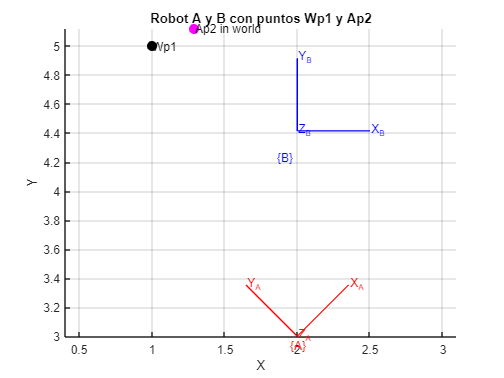

clc; clear; close all;

% --- Definir posiciones y orientaciones ---
% Robot A en coordenadas del mundo
A_pos = [2 3 0];          % X, Y, Z
A_theta = deg2rad(45);    % orientación en Z

% Robot B en coordenadas de Robot A
B_pos_A = [1 1 0];        % posición relativa a A
B_theta_A = deg2rad(-45); % orientación relativa a A

% Puntos
Wp1 = [1 5 0];  % en coordenadas del mundo
Ap2 = [1 2 0];  % en coordenadas del robot A

% --- Transformaciones homogéneas ---
TA = transl(A_pos) * trotz(A_theta);     % Robot A en mundo
%TB = TA * trotz(B_theta_A) * transl(B_pos_A); % Robot B en mundo
TB = TA * transl(B_pos_A) * trotz(B_theta_A);



% Punto Ap2 en mundo
P_Ap2_in_W = TA * [Ap2 1]';  % coordenadas homogéneas
P_Ap2_in_W = P_Ap2_in_W(1:3)';  % convertir a 3x1


% --- Graficar ---
figure; hold on; grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z'); view(2);

% Dibujar Robot A
trplot(TA, 'frame','A','color','r','length',0.5);

% Dibujar Robot B
trplot(TB, 'frame','B','color','b','length',0.5);

% Dibujar puntos
plot3(Wp1(1), Wp1(2), Wp1(3),'ko','MarkerSize',8,'MarkerFaceColor','k');
text(Wp1(1), Wp1(2), Wp1(3)+0.1,'Wp1');

plot3(P_Ap2_in_W(1), P_Ap2_in_W(2), P_Ap2_in_W(3),'mo','MarkerSize',8,'MarkerFaceColor','m');
text(P_Ap2_in_W(1), P_Ap2_in_W(2), P_Ap2_in_W(3)+0.1,'Ap2 in world');


title('Robot A y B con puntos Wp1 y Ap2');

% --- Mostrar valores en consola ---
disp('--- Coordenadas de marcos ---')

--- Coordenadas de marcos ---


fprintf('Robot A en mundo = [%.2f, %.2f, %.2f]\n', TA(1,4), TA(2,4), TA(3,4));

Robot A en mundo = [2.00, 3.00, 0.00]


fprintf('Robot B en mundo = [%.2f, %.2f, %.2f]\n', TB(1,4), TB(2,4), TB(3,4));

Robot B en mundo = [2.00, 4.41, 0.00]



disp('--- Puntos ---')

--- Puntos ---


fprintf('Wp1 en mundo    = [%.2f, %.2f, %.2f]\n', Wp1);

Wp1 en mundo    = [1.00, 5.00, 0.00]


fprintf('Ap2 en mundo    = [%.2f, %.2f, %.2f]\n', P_Ap2_in_W);

Ap2 en mundo    = [1.29, 5.12, 0.00]


b) ¿Cuáles son los coordenadas del punto p1 en el sistema de coordenadas del robot A? 

El punto 1 esta descripto en coordenadaes del mundo, con una pose $\overset{w}{\underset{1}{\xi}}$ y el robot A tambien se encuentra descripto con una pose en coordenadas del mundo $\overset{w}{\underset{A}{\xi}}$. Por lo que para obtener la pose del punto 1 respecto del marco de coordenadas A se debe hacer la composicion de la poses desde el punto 1 hasta el robot A.

Partiendo del robot A hasta el marco mundo tengo $\mathrm{inv}\left(\overset{w}{\underset{A}{\xi}} \right)$, y del marco mundo al punto 1 tengo $\overset{w}{\underset{1}{\xi}}$ por lo que $\overset{A}{\underset{1}{\xi}}$=$\overset{w}{\underset{1}{\xi}}$$*\mathrm{inv}\left(\overset{w}{\underset{A}{\xi}} \right)$     

% Punto Wp1 en coordenadas homogéneas
Wp1_h = [Wp1 1]';

% Transformar al marco de A
P_Wp1_in_A = inv(TA) * Wp1_h;
P_Wp1_in_A = P_Wp1_in_A(1:3)'

P_Wp1_in_A =     0.7071    2.1213         0


c) ¿Cuáles son los coordenadas del punto p2 en el sistema de coordenadas del robot B? 

El punto 2 y el robot B estan descriptos en coordenadas A, por lo que es un caso similar al anterior

$\overset{B}{\underset{2}{\xi}}$=$\overset{A}{\underset{2}{\xi}}$$*\mathrm{inv}\left(\overset{A}{\underset{B}{\xi}} \right)$    

% Punto Ap2 en A (homogéneo)
Ap2_h = [Ap2 1]';

% Transformación de A a B
T_BA = inv(TB) * TA;

% Punto Ap2 expresado en B
P_Ap2_in_B = T_BA * Ap2_h;
P_Ap2_in_B = P_Ap2_in_B(1:3)'

P_Ap2_in_B =    -0.7071    0.7071         0


d) ¿Cuál es la pose (posición y orientación) del robot B en coordenadas del Mundo? 

Dado que el robot B se encuentra descripto respecto de la pose del robot A y este ultimo respecto del mundo, hay que hacer la composicion de las poses pasando por el robot A

$\overset{W}{\underset{B}{\xi}}$=$\overset{W}{\underset{A}{\xi}}$$*\overset{A}{\underset{B}{\xi}}$  

TB = TA * transl(B_pos_A) * trotz(B_theta_A);

% Matriz de rotación (3x3)
R_B_in_W = TB(1:3,1:3);

% Posición (3x1)
p_B_in_W = TB(1:3,4)

p_B_in_W =     2.0000
    4.4142
         0



% Orientación como ángulo en Z (yaw)
theta_B_in_W_deg = rad2deg(theta_B_in_W)           % en grados

theta_B_in_W_deg = 0

## Ejercicio 4 

Data la pose del robot (Body) en el mundo: WξB0 . Si se tiene el camino (conjunto de poses C0 ξCi con i = 1 . . . n) realizado por la cámara C (montada sobre el robot) en el marco de coordenadas de la cámara inicial C0. Sabiendo la transformación BξC, 

A) ¿Qué procedimiento hay que realizar para obtener el camino realizado por la cámara en el sistema de coordenadas del mundo?

B) ¿Qué procedimiento hay que realizar para obtener el camino realizado por el robot (Body) en el sistema de coordenadas del mundo? 

C) Realizar un gráfico ilustrativo donde se visualicen los sistemas de coordenadas, las transformaciones y los caminos realizados por el robot y la cámara. 

Datos: 

Pose del robot respecto del mundo: $\overset{W}{\underset{B}{\xi}}$

Pose de la carama respecto del robot: $\overset{B}{\underset{C}{\xi}}$

Camino de la camara: $\overset{\mathrm{C0}}{\underset{\mathrm{Ci}}{\xi}}$

A) Camino de la camara respecto del mundo:

Hay que obtener la pose de la camara respecto del mundo, $\overset{W}{\underset{C}{\xi}} =\overset{W}{\underset{B}{\xi}} *\overset{B}{\underset{C}{\xi}}$  y una vez que se obtiene la pose de la camara respecto del mundo se debe componer el camino obtenido por la camara $\overset{W}{\underset{\mathrm{C0}-\mathrm{Ci}}{\xi}} =\overset{W}{\underset{C}{\xi}} *\overset{\mathrm{C0}}{\underset{\mathrm{Ci}}{\xi}}$

B) Camino del robot respecto del mundo

Hay que obtener el camino en coordenadas del robot,  $\overset{\mathrm{B0}}{\underset{\mathrm{Bi}}{\xi}} =\overset{\mathrm{C0}}{\underset{\mathrm{Ci}}{\xi}} *\mathrm{inv}\left(\overset{B}{\underset{C}{\xi}} \right)$ y ahora al camino en coordenadas del robot hay que transformarlo a las cordenadas mundo $\overset{W}{\underset{\mathrm{B0}-\mathrm{Bi}}{\xi}} =\overset{W}{\underset{B}{\xi}} *\overset{\mathrm{B0}}{\underset{\mathrm{Bi}}{\xi}}$

C) Realizar un gráfico ilustrativo donde se visualicen los sistemas de coordenadas, las transformaciones y los caminos realizados por el robot y la cámara.